# **Hourly energy demand generation and weather**

Este dataset contiene cuatro años de información de demanda eléctrica de España. En al documentación se puede apreciar como el archivo:

- `energy_dataset.csv`: incluye 35 064 registros (fila por hora) y 29 columnas.

energy_demand = readtable('data\hourly_energy_demand\energy_dataset.csv', 'Delimiter', ',', 'VariableNamingRule', 'preserve');

Como atributos se tiene la **producción eléctrica por tipo de fuente** (biomasa, diferentes categorías de combustibles fósiles, varias tecnologías hidroeléctricas, nuclear, solar, eólica, residuos, etc.), las **cargas totales previstas y reales**, y, los **precios de la electricidad**.

energy_column = energy_demand.Properties.VariableNames';

Luego se tiene un segundo archivo:

- `weather_features. csv`: incluye 178 369 observaciones y 17 variables meteorológicas como temperatura, presión y humedad.

% weather_state = readtable('data\hourly_energy_demand\weather_features.csv', 'Delimiter', ',', 'VariableNamingRule', 'preserve');
% weather_column = weather_state.Properties.VariableNames';

Sin embargo, y por efectos de tiempo, el análisis se centró en las variables energéticas debido a que se tiene un mayor entendimiento que a las condiciones atmosféricas.

## Preprocesado de datos

#### Limpieza de tiempo y rasgos temporales

% Cambia de string a formato datatime
energy_demand.time = datetime(energy_demand.time, 'InputFormat','yyyy-MM-dd HH:mm:ssXXX', 'TimeZone','UTC');

% Tabla de características agregadas. Preprocesamiento
energy_feat = table();

% Rasgos temporales
t  = energy_demand.time;
energy_feat.time = t;
energy_feat.hour = hour(t);
energy_feat.dayofweek = mod(weekday(t) + 5, 7);
energy_feat.month = month(t);

#### Selección y agregación de variables energéticas

% Helper: suma segura de columnas existentes
sumCols = @(T, cols) sum(T{:, intersect(cols, T.Properties.VariableNames, 'stable')}, 2, 'omitnan');

% Variables sumadas
energy_feat.generation_fossil_fuel = sumCols(energy_demand, energy_column(3:9));
energy_feat.generation_hydro = sumCols(energy_demand, energy_column(11:14));
energy_feat.generation_wind_total = sumCols(energy_demand, energy_column(21:22));

% Variables individuales
energy_feat.generation_solar = energy_demand.("generation solar");
energy_feat.generation_nuclear = energy_demand.("generation nuclear");

% Cargas y precios
energy_feat.total_load_actual = energy_demand.("total load actual");
energy_feat.total_load_forecast = energy_demand.("total load forecast");
energy_feat.price_day_ahead = energy_demand.("price day ahead");
energy_feat.price_actual = energy_demand.("price actual");

#### Tabla preprocesada

energy_feat;

# **K-Means**

#### Selección de atributos y preparación

Se planea trabajar con `total_load_actual` (demanda real) y `price_day_ahead` (precio día-anterior). Dado que capturan una relación económico-operativa bastante intuitiva. La demanda suele influir en la formación de precios; por tanto, los clústeres pueden reflejar regímenes de operación (p. ej., baja demanda/precios bajos vs. alta demanda/precios altos).

% 1) Extraer las dos columnas elegidas
featNames = {'total_load_actual','price_day_ahead'};
Xraw = energy_feat{:, featNames};

% 2) Eliminar filas con ausencias (para evitar NaN en métricas)
ok = ~any(ismissing(Xraw), 2);
Xraw = Xraw(ok, :);

% 3) Estandarizar (z-score) para que ambas características pesen igual
%    (K-Means es sensible a escala; evita que la variable con mayor varianza domine).
X = zscore(Xraw);

% (Opcional) fijar semilla para reproducibilidad del ejemplo en clase
rng(42);

### **Estimación del número de clústeres **

#### **Método del codo**

maxK = 10;                      % puedes ajustar este máximo
Klist = 1:maxK;
SSE  = zeros(size(Klist));     % Within-Cluster Sum of Squares

opts = statset('UseParallel',false,'MaxIter',300,'Display','final');

for i = 1:numel(Klist)
    k = Klist(i);
    % kmeans devuelve la suma de distancias por clúster en 'sumd'
    % con distancia euclídea por defecto.
    [~, ~, sumd] = kmeans(X, k, ...
        'Replicates', 5, ...           % varias inicializaciones para estabilidad
        'Options', opts, ...
        'MaxIter', 300, ...
        'OnlinePhase','on', ...
        'Start','plus');                % k-means++ (mejor inicialización)
    
    SSE(i) = sum(sumd);
end

Replicate 1, 2 iterations, total sum of distances = 70054.
Replicate 2, 2 iterations, total sum of distances = 70054.
Replicate 3, 2 iterations, total sum of distances = 70054.
Replicate 4, 2 iterations, total sum of distances = 70054.
Replicate 5, 2 iterations, total sum of distances = 70054.
Best total sum of distances = 70054
Replicate 1, 12 iterations, total sum of distances = 35405.8.
Replicate 2, 10 iterations, total sum of distances = 35405.8.
Replicate 3, 12 iterations, total sum of distances = 35405.8.
Replicate 4, 10 iterations, total sum of distances = 35405.8.
Replicate 5, 16 iterations, total sum of distances = 35405.8.
Best total sum of distances = 35405.8
Replicate 1, 19 iterations, total sum of distances = 27852.8.
Replicate 2, 18 iterations, total sum of distances = 27852.8.
Replicate 3, 27 iterations, total sum of distances = 26518.2.
Replicate 4, 28 iterations, total sum of distances = 26518.2.
Replicate 5, 22 iterations, total sum of distances = 27852.8.
Best total 

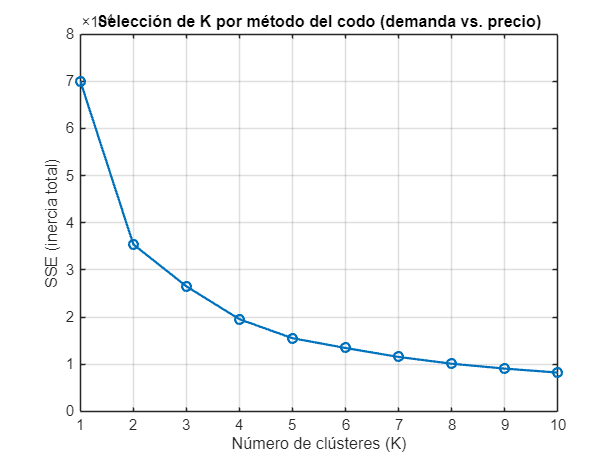


% --- Gráfico del codo ---
figure('Name','Método del codo');
plot(Klist, SSE, '-o','LineWidth',1.5);
grid on;
xlabel('Número de clústeres (K)');
ylabel('SSE (inercia total)');
title('Selección de K por método del codo (demanda vs. precio)');

drawnow; snapnow;   % fuerza el render y el snapshot en Live Editor

K_codo = 3;

#### Coeficiente de silueta

opts  = statset('UseParallel',false,'MaxIter',300,'Display','off');
Klist = 2:10;

clusterer = @(Y,K) kmeans(Y, K, ...
    'Replicates', 5, ...
    'Options',    opts, ...
    'MaxIter',    300, ...
    'OnlinePhase','on', ...
    'Start',      'plus');   % usa 'plus' (k-means++) para estabilidad

eva = evalclusters(X, clusterer, 'silhouette', 'KList', Klist)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 35028
         InspectedK: [2 3 4 5 6 7 8 9 10]
    CriterionValues: [0.6057 0.5316 0.5339 0.5344 0.4902 0.4958 0.5123 0.4998 0.4941]
           OptimalK: 2


  Properties, Methods



% Mostrar el K óptimo detectado
K_silueta = eva.OptimalK;
fprintf('K óptimo por silueta (evalclusters): %d\n', K_silueta);

K óptimo por silueta (evalclusters): 2


### Gráfico de K-Means

#### Método del codo

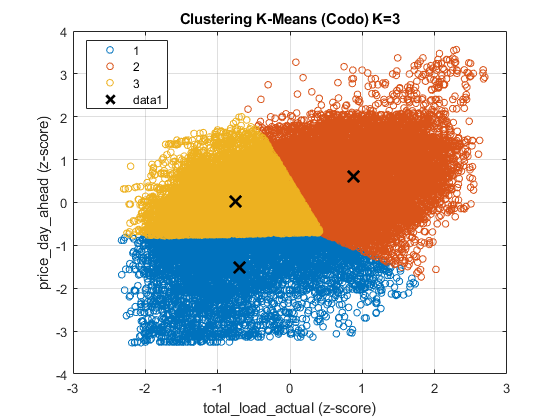

K = K_codo;
[idx, C] = kmeans(X, K, ...
    'Replicates', 5, ...
    'Options', opts, ...
    'MaxIter', 300, ...
    'OnlinePhase','on', ...
    'Start','plus');

% --- Dispersión 2D con centroides ---
fh1 = figure('Visible','on','Color','w', ...
    'Name',sprintf('K-Means (Codo) K=%d (Estandarizado)',K));
gscatter(X(:,1), X(:,2), idx, lines(K), 'o', 5); hold on;
plot(C(:,1), C(:,2), 'kx', 'MarkerSize',12, 'LineWidth',2);
grid on; box on;
xlabel('total\_load\_actual (z-score)');
ylabel('price\_day\_ahead (z-score)');
title(sprintf('Clustering K-Means (Codo) K=%d', K));
legend('Location','best');
hold off;

drawnow; snapnow;   % fuerza el render y el snapshot en Live Editor

#### Coeficiente de Silueta

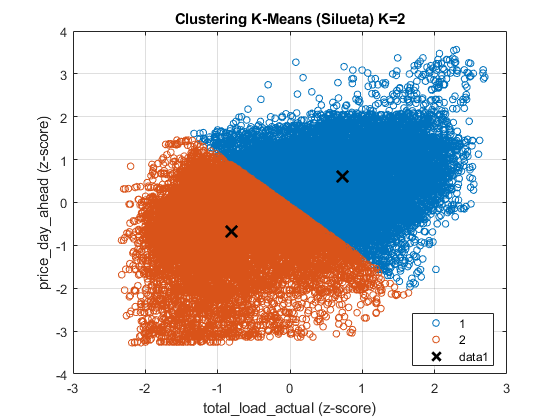

K = K_silueta;
[idx, C] = kmeans(X, K, ...
    'Replicates', 5, ...
    'Options', opts, ...
    'MaxIter', 300, ...
    'OnlinePhase','on', ...
    'Start','plus');

% --- Dispersión 2D con centroides ---
fh2 = figure('Visible','on','Color','w', ...
    'Name',sprintf('K-Means (Silueta) K=%d (Estandarizado)',K));
gscatter(X(:,1), X(:,2), idx, lines(K), 'o', 5); hold on;
plot(C(:,1), C(:,2), 'kx', 'MarkerSize',12, 'LineWidth',2);
grid on; box on;
xlabel('total\_load\_actual (z-score)');
ylabel('price\_day\_ahead (z-score)');
title(sprintf('Clustering K-Means (Silueta) K=%d', K));
legend('Location','best');
hold off;

drawnow; snapnow;

# **Lectura de los dos gráficos**

### **K = 3 (codo)**

- El algoritmo crea **tres regiones tipo “rebanadas”** (fronteras lineales por Voronoi).

- Ventaja: **baja más la inercia (WCSS)** porque reparte mejor la varianza, sobre todo en colas/zonas de baja densidad.

- Desventaja: el clúster izquierdo parece **“forzado”** por la forma continua del dato; las fronteras cortan una nube continua y los clústeres quedan **menos separados**.

**Clúster A (bajo precio – baja demanda)**

- Horas valle: **madrugada/fin de semana** suelen concentrarse aquí.

- Mayor probabilidad de **oferta renovable suficiente** (eólica/hidro embalse/vertidos) frente a la demanda.

- Interpretación operativa: **sistema desahogado**; el precio marginal lo marcan tecnologías de bajo coste variable o la abundancia renovable.

**Clúster B (alto precio – alta demanda)**

- Horas pico: **tardes laborales** y **puntas estacionales** (frío/calor).

- Más probables **térmicas** en el margen, restricciones de red, rampas fuertes o **reservas escasas**.

- Interpretación: **régimen de estrés** de corto plazo; el precio sube con la carga.

### K=2 (silueta, derecha)

- Partición **diagonal** más natural respecto al eje principal de la nube.

- Los dos clústeres quedan **más compactos y separados**, lo que **eleva la silueta**.

- Interpretación sencilla en clase: **régimen bajo** vs **régimen alto** de demanda-precio.

**Bajo precio – baja demanda** (franja inferior)

- Horas valle más profundas; mucha parte de la nube por debajo de la media de precio.

- *Lectura*: abundancia relativa de oferta; posible viento nocturno/hidro base.

**Transición (demanda baja/moderada – precio entorno a la media)** (rejón izquierdo)

- Periodos **hombro** (post-valle / pre-pico) o fines de semana de **media actividad**.

- *Lectura*: la relación precio-demanda no es tan marcada; puede haber mezcla de tecnologías, rampas o pequeñas restricciones locales.

**Alto precio – alta demanda** (franja superior-derecha)

- Picos diarios y estacionales; probables tecnologías marginales más caras.

- *Lectura*: régimen de **escasez relativa**.

### ¿Por qué el codo te da K=3 y la silueta K=2?

- **Codo (WCSS/inercia)** mide **cuánta varianza interna reduces** al añadir clústeres. En nubes **elongadas y continuas** (como la tuya), añadir un tercer centro **siempre** reduce WCSS de forma visible, de ahí el “quiebre” en **K=3**.

- **Silueta** premia **separación y compacidad**. Si el tercer clúster **corta una nube continua** sin crear grupos bien separados, la silueta **no mejora** e incluso baja, por eso aboga por **K=2**.**Traducción:** *explicar más varianza ≠ separar mejor*. Para docencia/interpretación, **K=2** suele ser mejor aquí.

### Notas sobre outliers y su efecto

- **Outliers/picos** (horas con precio o demanda anómalamente altos/bajos):

- Empujan el **codo** a **K** mayores (más centros = menos WCSS).

- Pueden **degradar** la **silueta** (cohesión/separación peores).

### Recomendación práctica para el video

Presenta **ambos criterios**:

- Codo → explica por qué K=3 reduce más WCSS pero no implica mejor separación.

- Silueta → muestra que **K=2** obtiene mayor separación/cohesión en esta nube.

Luego, **fija K=2** para el ejemplo docente y discute cómo **outliers** y la **forma elíptica** influyen en los criterios.